# **Electrode+Water LAMMPS Simulations**

Checking equilibrium and water distribution/RDF

See equilibriation

## LAMMPS Output Files

### RDF Output File

rdf = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\grouped\tip4p_cs_2V_ar_long\tip4p_Cs_2V.rdf";

### Z Distribution Output File

#### Water

z_h2o = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\grouped\tip4p_cs_2V_ar_long\tip4p_Cs_2V_1elec.dens";

#### Cation

z_cat = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\grouped\tip4p_cs_2V_ar_long\cat_Cs_2V_1elec.dens";

#### Reference Electrode

z_elec = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\grouped\tip4p_cs_2V_ar_long\Pt_cat_atom_1elec.dens";

### Thermo Output File

thermo = "C:\Users\sunsk\MATLAB\LAMMPS\Logs\grouped\tip4p_cs_2V_ar_long\log.lammps";

## Timing and Step Details

### General

Dimensions

zlo = -0.5;
zhi = 50;

Time Units set in LAMMPS

time_units = 1000;

Timestep of Simulation

timestep = 1/time_units;

Number of Steps

numSteps = 250000;
maxTime = timestep*numSteps;

### RDF

Steps between each RDF print. How many bins per timestep. Cutoff distance for RDF.

perStep_rdf = 1000;
maxSteps_rdf = numSteps/perStep_rdf;
binNum = 1000;
cutoff = 10;

### Z Distribution

perStep_Z = 10000;
maxSteps_Z = numSteps/perStep_Z;

### Thermo

perStep_thermo = 500;
maxSteps_thermo = numSteps/perStep_thermo;

## Outputs-RDF

%Process RDF data
[time_rdf,Bins_rdf,rdf_ave_oh,rdf_ave_hh,rdf_ave_oo] = h2o_rdf(rdf,maxSteps_rdf,binNum);

time_rdf = time_rdf(~isnan(time_rdf),:)*timestep;

%Averaging the time distribution functions
rdf_m_ave_oh = move_avg(rdf_ave_oh,5,true);
rdf_m_ave_hh = move_avg(rdf_ave_hh,5,true);
rdf_m_ave_oo = move_avg(rdf_ave_oo,5,true);

### Time-Evolution of Average Radial Distribution

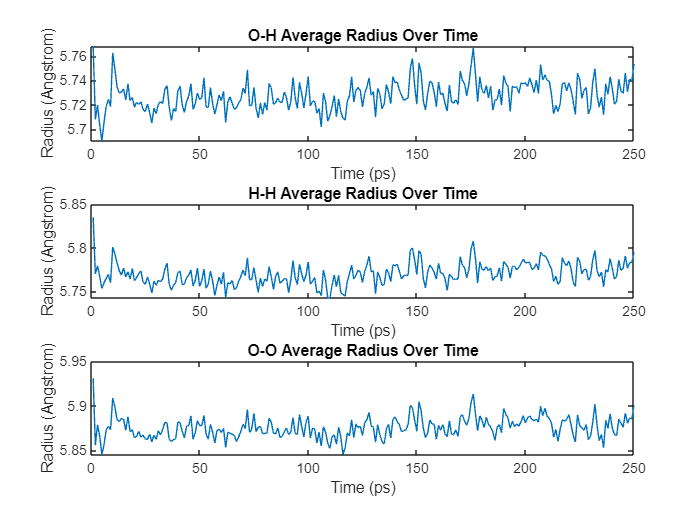

time_label = "Time (ps)";
figure
subplot(3,1,1);
plot(time_rdf,rdf_ave_oh);
title("O-H Average Radius Over Time");
xlabel(time_label);
ylabel("Radius (Angstrom)");
subplot(3,1,2);
plot(time_rdf,rdf_ave_hh);
title("H-H Average Radius Over Time");
xlabel(time_label);
ylabel("Radius (Angstrom)");
subplot(3,1,3);
plot(time_rdf,rdf_ave_oo);
title("O-O Average Radius Over Time");
xlabel(time_label);
ylabel("Radius (Angstrom)");

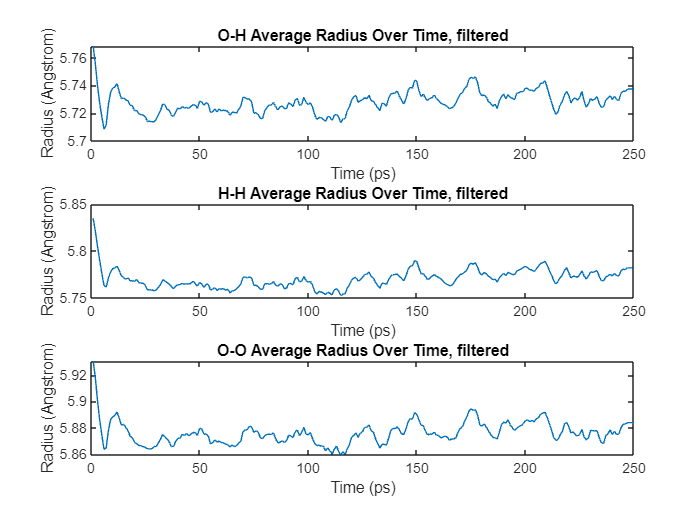

figure
subplot(3,1,1);
plot(time_rdf,rdf_m_ave_oh);
title("O-H Average Radius Over Time, filtered");
xlabel(time_label);
ylabel("Radius (Angstrom)");
subplot(3,1,2);
plot(time_rdf,rdf_m_ave_hh);
title("H-H Average Radius Over Time, filtered");
xlabel(time_label);
ylabel("Radius (Angstrom)");
subplot(3,1,3);
plot(time_rdf,rdf_m_ave_oo);
title("O-O Average Radius Over Time, filtered");
xlabel(time_label);
ylabel("Radius (Angstrom)");

### Plot RDF at timestep

Plot up to 3 rdf plots on the same plot. timeStep# is in units of rdf prints.

Use 0 for don't plot. Messes up the legend if the 0 is not at the end. 

timeStep1 =1;
if(timeStep1 > maxSteps_rdf)
    timeStep1 = maxSteps_rdf;
end
timeStep2 =20;
if(timeStep2 > maxSteps_rdf)
    timeStep2 = maxSteps_rdf;
end
timeStep3 =250;
if(timeStep3 > maxSteps_rdf)
    timeStep3 = maxSteps_rdf;
end

legend_text = [strcat(string(timeStep1*timestep*perStep_rdf)," ps") ...
                strcat(string(timeStep2*timestep*perStep_rdf)," ps") ...
                strcat(string(timeStep3*timestep*perStep_rdf)," ps")];

warning('off','matlab:legend:IgnoringExtraEntries'); %Turn off warning when -1 is used

if timeStep1 ~= 0
    rdfOH1 = Bins_rdf(:,3,timeStep1);
    rdf_ave_OH1 = move_avg(rdfOH1,10,true);
    rdfHH1 = Bins_rdf(:,5,timeStep1);
    rdf_ave_HH1 = move_avg(rdfHH1,10,true);
    rdfOO1 = Bins_rdf(:,7,timeStep1);
    rdf_ave_OO1 = move_avg(rdfOO1,10,true);
end

if timeStep2 ~= 0
    rdfOH2 = Bins_rdf(:,3,timeStep2);
    rdf_ave_OH2 = move_avg(rdfOH2,10,true);
    rdfHH2 = Bins_rdf(:,5,timeStep2);
    rdf_ave_HH2 = move_avg(rdfHH2,10,true);
    rdfOO2 = Bins_rdf(:,7,timeStep2); 
    rdf_ave_OO2 = move_avg(rdfOO2,10,true);
end
if timeStep3 ~= 0
    rdfOH3 = Bins_rdf(:,3,timeStep3);
    rdf_ave_OH3 = move_avg(rdfOH3,10,true);
    rdfHH3 = Bins_rdf(:,5,timeStep3); 
    rdf_ave_HH3 = move_avg(rdfHH3,10,true);
    rdfOO3 = Bins_rdf(:,7,timeStep3); 
    rdf_ave_OO3 = move_avg(rdfOO3,10,true);
end

#### RDF Plots

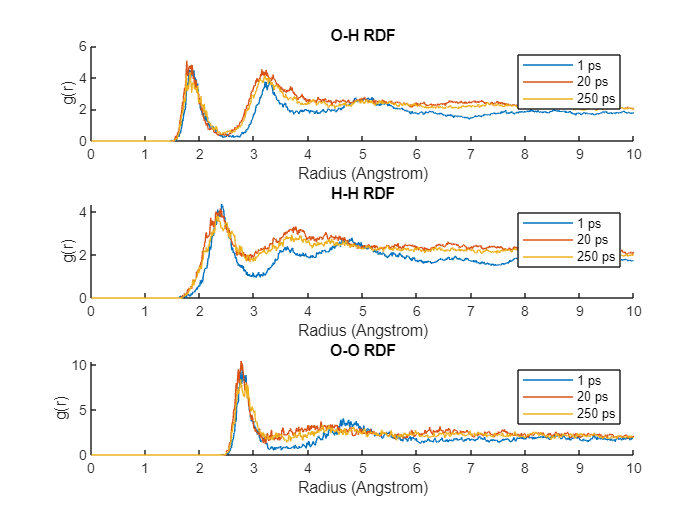

figure
subplot(3,1,1);
hold on;
if timeStep1 ~= 0
    plot(Bins_rdf(:,2,1),rdfOH1);
end
if timeStep2 ~= 0
    plot(Bins_rdf(:,2,1),rdfOH2);
end
if timeStep3 ~= 0
    plot(Bins_rdf(:,2,1),rdfOH3);
end
hold off;
title("O-H RDF");
xlabel("Radius (Angstrom)");
ylabel("g(r)");
legend(legend_text);
subplot(3,1,2);
hold on;
if timeStep1 ~= 0
    plot(Bins_rdf(:,2,1),rdfHH1);
end
if timeStep2 ~= 0
    plot(Bins_rdf(:,2,1),rdfHH2);
end
if timeStep3 ~= 0
    plot(Bins_rdf(:,2,1),rdfHH3);
end
hold off;
title("H-H RDF");
xlabel("Radius (Angstrom)");
ylabel("g(r)");
legend(legend_text);
subplot(3,1,3);
hold on;
if timeStep1 ~= 0
    plot(Bins_rdf(:,2,1),rdfOO1);
end
if timeStep2 ~= 0
    plot(Bins_rdf(:,2,1),rdfOO2);
end
if timeStep3 ~= 0
    plot(Bins_rdf(:,2,1),rdfOO3);
end
hold off;
title("O-O RDF");
xlabel("Radius (Angstrom)");
ylabel("g(r)");
legend(legend_text);

#### Filtered RDF Plots

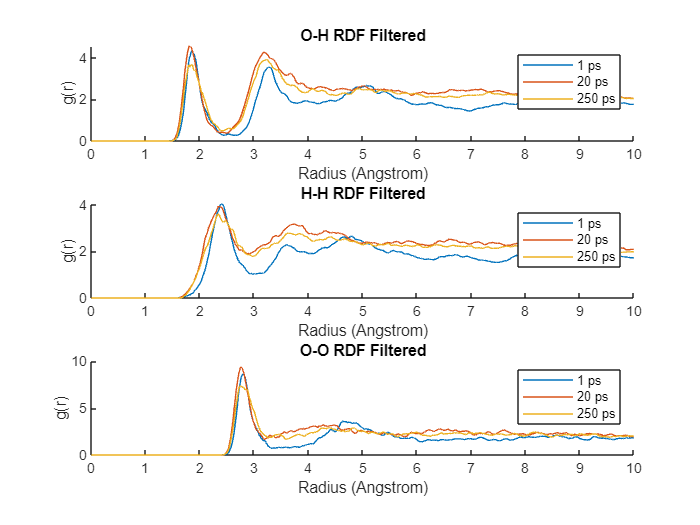

figure
subplot(3,1,1);
hold on;
if timeStep1 ~= 0
    plot(Bins_rdf(:,2,1),rdf_ave_OH1);
end
if timeStep2 ~= 0
    plot(Bins_rdf(:,2,1),rdf_ave_OH2);
end
if timeStep3 ~= 0
    plot(Bins_rdf(:,2,1),rdf_ave_OH3);
end
hold off;
title("O-H RDF Filtered");
xlabel("Radius (Angstrom)");
ylabel("g(r)");
legend(legend_text);
subplot(3,1,2);
hold on;
if timeStep1 ~= 0
    plot(Bins_rdf(:,2,1),rdf_ave_HH1);
end
if timeStep2 ~= 0
    plot(Bins_rdf(:,2,1),rdf_ave_HH2);
end
if timeStep3 ~= 0
    plot(Bins_rdf(:,2,1),rdf_ave_HH3);
end
hold off;
title("H-H RDF Filtered");
xlabel("Radius (Angstrom)");
ylabel("g(r)");
legend(legend_text);
subplot(3,1,3);
hold on;
if timeStep1 ~= 0
    plot(Bins_rdf(:,2,1),rdf_ave_OO1);
end
if timeStep2 ~= 0
    plot(Bins_rdf(:,2,1),rdf_ave_OO2);
end
if timeStep3 ~= 0
    plot(Bins_rdf(:,2,1),rdf_ave_OO3);
end
hold off;
title("O-O RDF Filtered");
xlabel("Radius (Angstrom)");
ylabel("g(r)");
legend(legend_text);

## Outputs-Z Distribution

%Process Z-Distribution Data
[time_h2odens, Bins_h2odens] = zDens(z_h2o,maxSteps_Z);
[time_catdens, Bins_catdens] = zDens(z_cat,maxSteps_Z);
[time_elecdens, Bins_elecdens] = zDens(z_elec,maxSteps_Z);

scaling = zhi-zlo; %For reduced units -- forced for triclinic
%scaling = 1; %for box units


Print-step of Z-density.

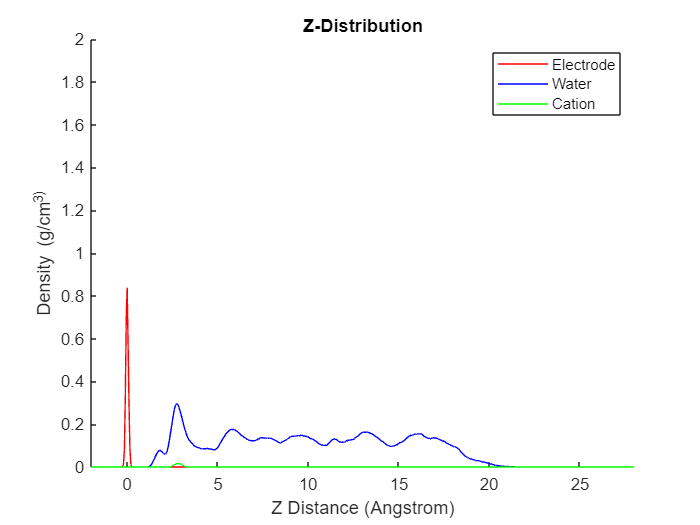

timeStep_z =25;
if(timeStep_z > maxSteps_rdf)
    timeStep_z = maxSteps_rdf;
end

densH2O = cell2mat(Bins_h2odens(timeStep_z,:));
densH2O_dens = move_avg(densH2O(:,4),10,true);
densCat = cell2mat(Bins_catdens(timeStep_z,:));
densCat_dens = move_avg(densCat(:,4),10,true);
densElec = cell2mat(Bins_elecdens(timeStep_z,:));

displacement = 7.35;
figure
hold on;
plot(densElec(:,2).*scaling-displacement,densElec(:,4),'r-');
plot(densH2O(:,2).*scaling-displacement,densH2O_dens,'b');
plot(densCat(:,2).*scaling-displacement,densCat_dens,'g');
xlabel("Z Distance (Angstrom)");
ylabel("Density (g/cm^3)");
title("Z-Distribution");
legend(["Electrode" "Water" "Cation"]);
axis([-2 28 0 2]);
hold off;

## Outputs-Energy Evolution

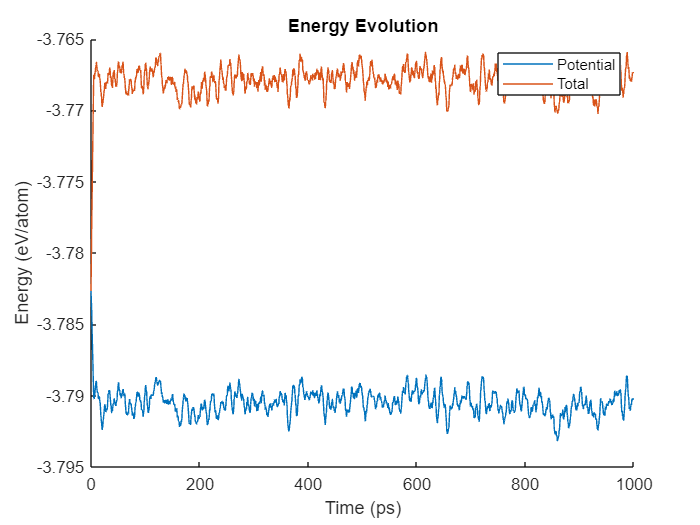

%Step         PotEng         KinEng         TotEng          Temp          Press          Volume
[Thermo_table, numAtoms] = parse_Out(thermo);

Thermo_table.PotEng = move_avg(Thermo_table.PotEng,10,true);
Thermo_table.TotEng = move_avg(Thermo_table.TotEng,10,true);
figure
hold on;
plot(Thermo_table.Step.*timestep,Thermo_table.PotEng);
plot(Thermo_table.Step.*timestep,Thermo_table.TotEng);
hold off;
xlabel("Time (ps)");
ylabel("Energy (eV/atom)");
title("Energy Evolution");
legend(["Potential" "Total"]);

%axis([-Inf Inf -2 0]);
warning('on','matlab:legend:IgnoringExtraEntries');